# Nonlinear Regression, Newton-Raphson Method, Bisection Method, and Eigenvalues

Due Date:  21st March 2024

Student Name: Marc-Antoine Nadeau

Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

Please submit this **.mlx** file along with a **PDF** copy of this file.

Note: You can write the function in the appendix section using the provided stencils.

**In this assignment you may use the backslash operator, '\' to solve systems such as Ax=b for questions involving solutions of nonlinear equations only.**

clear all;

## Question 1:  Linear Regression Revisited

Suppose we are given the following equations,

$M\;\mathit{\mathbf{a}}=\mathit{\mathbf{y}}$,  $M \in \mathbb{R}^{m\times n}$ with $m>n$

We want to fit a $n^{\textrm{th}}$degree polynomial, $p\left(x\right)=a_0 +a_1 x+a_{2\;} x^{2\;} +a_3 x^3 +\cdots +a_{n\;} x^n$. To find the coefficicients,  $\mathit{\mathbf{a}}=\left\lbrack a_{0\;} ,\;\;a_1 ,\;\;a_2 ,\cdots a_n \right\rbrack$, we can solve the linear system shown below. 


$$\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
1 & x_{2\;}  & x_{2\;}^2  & \cdots \; & x_{2\;}^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_{m-1}  & x_{m-1}^2  & \cdots  & x_{m-1}^n \\
1 & x_m  & x_m^2  & \cdots \; & x_m^n 
\end{array}\right\rbrack } }$$

$$\underset{\mathit{\mathbf{a}}}{\underbrace{\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
a_n 
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{y}}}{\underbrace{\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
y_{m-1} \\
y_m 
\end{array}\right\rbrack } }$$


You are given the following data, your data is loaded and plotted in the cell below. Make sure the provided data files are present in the same directory as this script.

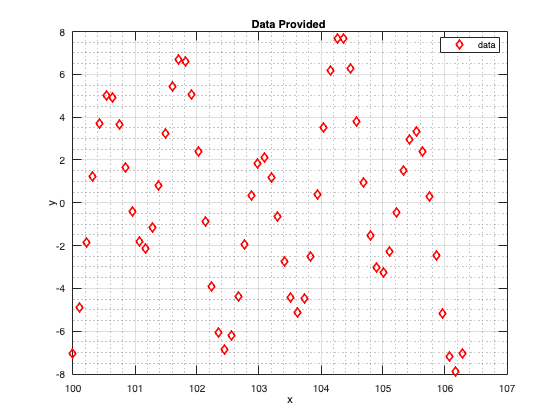

load('/Users/marc-antoinenadeau/Desktop/4th Semester/ECSE 343/Assignments/A3/Asst3_data_Q1a.mat'); % load the data 

x = x_given;
y = y_given;

figure
plot(x,y, 'rd',"LineWidth",2,"DisplayName",'data')
legend("Location","best") 
xlabel('x') ;ylabel('y')
grid on; grid minor
title('Data Provided ')

a. Using the code you wrote in Assignment 2, construct the Vandermonde matrix, M, for the data provided. Suppose we choose to model the provided data with a polynomial of **degree 17**. Using the cell below, fit a polynomial of degree 17**, **i.e. $p(x) = a_0 + a_1 x + a_2 x^2 + \dots + a_{17} x^{17}$.  You can use the MATLAB's QR decomposition function to find the polynomial coefficients.

% Set Degree
degree = 17; 

% Construct the Vandermond matrix
M = PolynomialMatrix(x,degree);

% Get Q and R matrix using MATLAB's QR method
[Q, R] = qr(M);

% Get the Coefficients
coefficents = R \ (Q'*y);

Now that you have obtained the coefficients, $a_i,  \;\;0\leq i \leq17$ , for the polynomial model, $p(x) = a_0 + a_1 x + a_2 x^2 + \dots + a_{17} x^{17}$, we can test this model by evaluating $p\left(x\right)$ at different values of $x$. Since the input data was linearly spaced between 100 to $100+2\pi \;$, you can use 200 linearly spaced points to test the performance of your model.

In the cell below, use the data you used to build the model as reference to test the performance of the obtained model by plotting it on the same plot.  Make sure your plots axis are labeled and the plots must contain a title and a legend. 

Hint: You can use the code you used in Assignment 2.

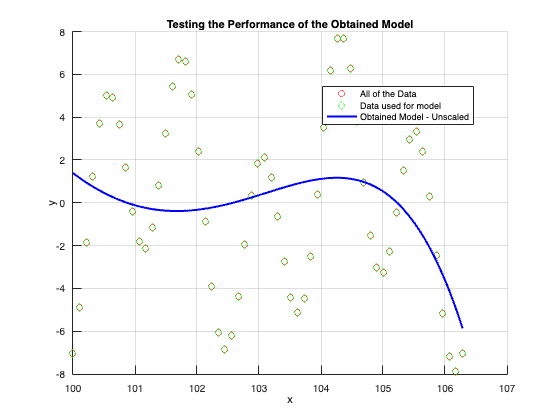

%----------------------------------------------------------------
x_test = linspace(100+0,100+2*pi,200);  % generate test data 
x_test = x_test';
%----------------------------------------------------------------
% Construct the Vandermond matrix
degree = 17;
Mp = PolynomialMatrix(x_test, degree);

% Evaluate the polynomial model using coefficients obtained
px_test = Mp * coefficents;

% Plotting
figure
hold on
plot(x_given, y_given, 'ro', 'DisplayName', 'All of the Data')
plot(x, y, 'gd', 'DisplayName', 'Data used for model')
plot(x_test, px_test, 'b-', 'LineWidth', 2, 'DisplayName', 'Obtained Model - Unscaled')             % Keep one
xlabel('x')
ylabel('y')
legend('Location', 'best')
title('Testing the Performance of the Obtained Model')
grid on

Is the model you obtained accurate? Suggest what you will do to improve the performance of the model.

- *The obtained model is not accurate. To be precise the model is underfitting the data as it is picking un on a trend which does not accurately match the underlying data. To improve the performance of the model we introduce scaling to the data: *


$$\begin{array}{l}
\textrm{Let}:\;\;a=\min \left(x\right)\;\textrm{and}\;b=\max \left(x\right)\;\\
{\;\;\;\;\;\;\;\;\;X}_{\textrm{scaled}} =\frac{2}{a-b}\left(x-\frac{a+b}{2}\right)
\end{array}$$


b. If the polynomial model you obtained in part a is not accurate, make appropriate changes to data to fit a polynomial model of order 17 shown in part a. Use the cell below to write your code. You can use the MATLAB's QR decomposition function to find the polynomial coefficients.

Plot the obtained model along with the data used to build the model. Make sure your plots axis are labeled and the plots must contain a title and a legend. 

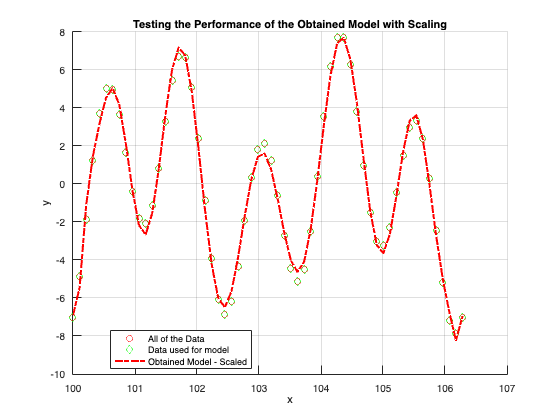

% *** Scaling the Coefficient Matrix ***
% Set Degree
degree = 17; 
a = min(x); b =max(x);
X_scaled = (2/(a-b))*(x - (a+b)/2);

% Construct the Vandermond matrix
Mp_Scaled = PolynomialMatrix(X_scaled,degree);

% Get Q and R matrix using MATLAB's QR method
[Q, R] = qr(Mp_Scaled);

% Get the Coefficients
coefficents_scaled = R \ (Q'* y);

% Evaluate the polynomial model using coefficients obtained
px_test_scaled = Mp_Scaled * coefficents_scaled;

% Plotting
figure
hold on
plot(x_given, y_given, 'ro', 'DisplayName', 'All of the Data')
plot(x, y, 'gd', 'DisplayName', 'Data used for model')
plot(x, px_test_scaled, 'r-.', 'LineWidth', 2, 'DisplayName', 'Obtained Model - Scaled')
xlabel('x')
ylabel('y')
legend('Location', 'best')
title('Testing the Performance of the Obtained Model with Scaling')
grid on

Write a brief summary on how you obtained the correct model.

- *In this version of the model, we introduced scaling to the data. Using the sclaing, the model accurately fits the sinusidioal trend of the data. As a reminder, to scale the data, we use the following technique: *


$$\begin{array}{l}
\textrm{Let}:\;\;a=\min \left(x\right)\;\textrm{and}\;b=\max \left(x\right)\;\\
{\;\;\;\;\;\;\;\;\;X}_{\textrm{scaled}} =\frac{2}{a-b}\left(x-\frac{a+b}{2}\right)
\end{array}$$


- The procedure to find the model is similar. We begin by scaling the data using the above method, then we compute the vandermonde matrix. Then we find the coefficent matrix, and finally we obtain the model p(x). Overall, we obtain a model that accurately fits the underlying data. 

c. In this part use the data set loaded in the cell below and repeat part b, fit a polynomial of degree 17, i.e. $p(x) = a_0 + a_1 x + a_2 x^2 + \dots + a_{17} x^{17}$ to the provided data. Comment on your results. Plot the obtained model along with the data used to build the model. Make sure your plots axis are labeled and the plots must contain a title and a legend. 

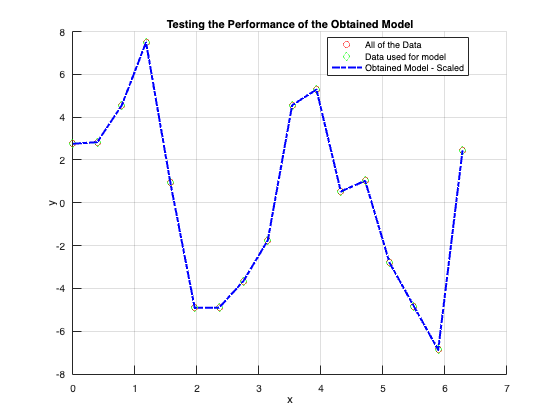

load('/Users/marc-antoinenadeau/Desktop/4th Semester/ECSE 343/Assignments/A3/Asst3_data_Q1c.mat');

x = x_given; % input data
y = y_given; % output data

% *** Scaling the Coefficient Matrix ***
% Set Degree
degree = 17;

a = min(x); b =max(x);
X_scaled = (2/(a-b))*(x - (a+b)/2); 

% Construct the Vandermond matrix
Mnew = PolynomialMatrix(X_scaled,degree);

% Get Q and R matrix using MATLAB's QR method
[Q, R] = qr(Mnew);

% Get the Coefficients
coefficents_scaled = R \ (Q'*y);

% Construct the Vandermond matrix
Mp_Scaled = PolynomialMatrix(X_scaled, degree);

% Evaluate the polynomial model using coefficients obtained
px_test_scaled = Mp_Scaled * coefficents_scaled;

% Plotting
figure
hold on
plot(x_given, y_given, 'ro', 'DisplayName', 'All of the Data')
plot(x, y, 'gd', 'DisplayName', 'Data used for model')
plot(x, px_test_scaled, 'b-.', 'LineWidth', 2, 'DisplayName', 'Obtained Model - Scaled')
xlabel('x')
ylabel('y')
legend('Location', 'best')
title('Testing the Performance of the Obtained Model')
grid on

d. For this part your task is to design a Tikhnov Regularisation based algorithm to fit the data using the polynomial of degree 17. Your algorithm must be optimised for **accuracy.**  Use the cell below to compute the coefficients of $17^{th}$ degree polynomial.  Use trial and error to choose the value of regularisation constant, $\lambda$.

Plot the obtained model along with the data used to build the model.

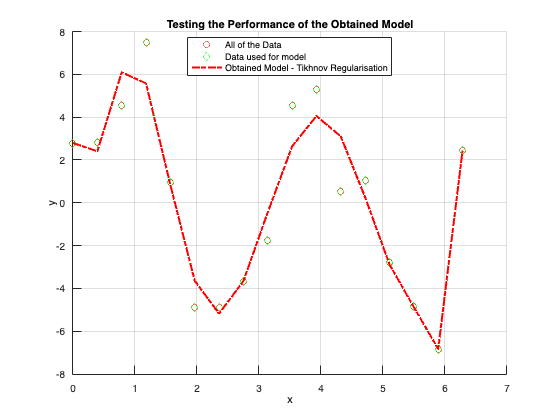

load('/Users/marc-antoinenadeau/Desktop/4th Semester/ECSE 343/Assignments/A3/Asst3_data_Q1c.mat');

x = x_given; % input data
y = y_given; % output data

% *** Scaling the Coefficient Matrix ***
% Set Degree
degree = 17;

a = min(x); b =max(x);
X_scaled = (2/(a-b))*(x - (a+b)/2); 

% Construct the Vandermond matrix
Mnew = PolynomialMatrix(X_scaled,degree);

% *** Reguralization ***
lambda = 1e-2;                              % May be changed as desired

Mreg = [Mnew ; lambda * eye(size(Mnew,2))];
breg = [y ; zeros(size(Mnew,2),1)];

coefficients_reg  = Mreg \ breg;             % solve the regularised system.

% Construct the Vandermond matrix
Mp_Reg = PolynomialMatrix(X_scaled, degree);


% Evaluate the polynomial model using coefficients obtained
px_reg = Mp_Reg * coefficients_reg;

figure
hold on
plot(x_given, y_given, 'ro', 'DisplayName', 'All of the Data')
plot(x, y, 'gd', 'DisplayName', 'Data used for model')
plot(x, px_reg, 'r-.', 'LineWidth', 2, 'DisplayName', 'Obtained Model - Tikhnov Regularisation')
xlabel('x')
ylabel('y')
legend('Location', 'best')
title('Testing the Performance of the Obtained Model')
grid on

e. Using the cell below, plots the models obtained in part c and d along with the data used in building the models. Comment on both models.

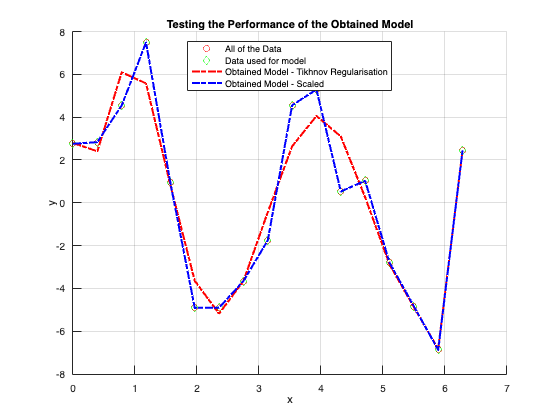

figure
hold on
plot(x_given, y_given, 'ro', 'DisplayName', 'All of the Data')
plot(x, y, 'gd', 'DisplayName', 'Data used for model')
plot(x, px_reg, 'r-.', 'LineWidth', 2, 'DisplayName', 'Obtained Model - Tikhnov Regularisation')
plot(x, px_test_scaled, 'b-.', 'LineWidth', 2, 'DisplayName', 'Obtained Model - Scaled')
xlabel('x')
ylabel('y')
legend('Location', 'best')
title('Testing the Performance of the Obtained Model')
grid on

- The model in c), here shown in blue, is unreguralized. This model is overfitting the data as seen by the sharp changes and by passing though all the data points. On the contrary, the model in d), here shown in red, is reguralized. This is model is a better fit for the model as it is  has a smoother shaper as opposed to the sharp chages in the model c). 

f. The least squares regression is used to build the models based on the experimental data. As the new the new experimental data is available the obtained model must be updated. In this part, you will design an algorithm to update the model coefficients when new data is available. Similar to the previous parts we trying to fit the polynomial based model to the provided data.  Suppose we have  m-data points, we can write our Vandermonde matrix system as,


$$\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_m  & x_m^2  & \cdots \; & x_m^n 
\end{array}\right\rbrack } }$$

$$\underset{\mathit{\mathbf{a}}}{\underbrace{\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
\vdots \\
a_n 
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{y}}}{\underbrace{\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
\vdots \\
y_m 
\end{array}\right\rbrack } }$$


Using the Normal equations, we know the least-square solution for the above system is given by


$${\mathit{\mathbf{M}}}^{T\;} \mathit{\mathbf{M}}\;\mathit{\mathbf{a}}={\mathit{\mathbf{M}}}^T \mathit{\mathbf{y}}$$


In the following cell using the data provided in the file named, Asst3_data_Q1f.mat, fit the polynomial of order 2 using the Normal Equations. Use the matrix ${\mathit{\mathbf{M}}}^{T\;} \mathit{\mathbf{M}}$explicitly, to compute the least square solution for the abovew system of equations. Choose the best algorithm to compute the solution.

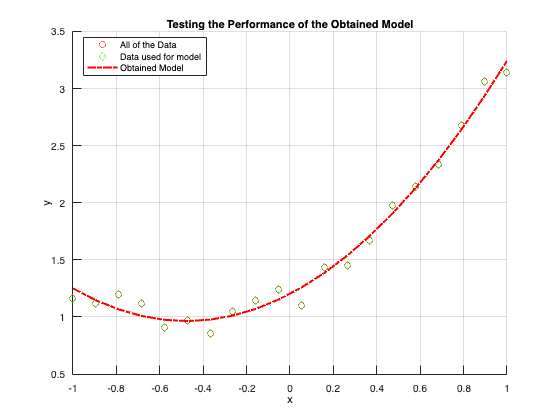

load('/Users/marc-antoinenadeau/Desktop/4th Semester/ECSE 343/Assignments/A3/Asst3_data_Q1f.mat'); 

x = x_given;
y = y_given;
% Setting Degree
degree = 2;

% Scaling
a = min(x); b =max(x);
X_scaled = (2/(a-b))*(x - (a+b)/2); 

% Producing Matrix M
M = PolynomialMatrix(X_scaled ,degree);

% TODO are we supposed to be using this here
% Computing Coefficent using M^T M directly 
B = M' * M;
coefficients = B \ (M' * y);

px = M * coefficients;


figure
hold on
plot(x_given, y_given, 'ro', 'DisplayName', 'All of the Data')
plot(x, y, 'gd', 'DisplayName', 'Data used for model')
plot(x, px, 'r-.', 'LineWidth', 2, 'DisplayName', 'Obtained Model')
xlabel('x')
ylabel('y')
legend('Location', 'best')
title('Testing the Performance of the Obtained Model')
grid on

After running the experiment, we obtained a new data $y_{m+1}$ for input $x_{m+1}$, using this we can update the above system as,


$$\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_m  & x_m^2  & \cdots \; & x_m^n \\
1 & x_{m+1}  & x_{m+1}^2  & \cdots \; & x_{m+1}^n 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\hat{a} }_0 \\
{\hat{a} }_1 \\
\vdots \\
{\hat{a} }_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
\vdots \\
y_m \\
y_{m+1} 
\end{array}\right\rbrack$$


Note that in the above system the coefficients will be updated. The above system can also we written as,


$$\left\lbrack \begin{array}{c}
\mathit{\mathbf{M}}\\
{\mathit{\mathbf{v}}}^T 
\end{array}\right\rbrack \hat{\mathit{\mathbf{a}}} =\left\lbrack \begin{array}{c}
\mathit{\mathbf{y}}\\
y_{m+1} 
\end{array}\right\rbrack \;$$


where, ${\mathit{\mathbf{v}}}^T$ is a row vector containing the polynomials evaluated at the input point $x_{m+1}$, i.e.,  ${\mathit{\mathbf{v}}}^T =\left\lbrack \begin{array}{ccccc}
1 & x_{m+1}  & x_{m+1}^2  & \cdots  & x_{m+1}^n 
\end{array}\right\rbrack$ and $\hat{\mathit{\mathbf{a}}}$ is a column vector containing the updated coeffcients. 

x_mplus1 =  -3.1579e-01;
y_mplus1 =  1.5;

% form your vT vector
vT = zeros(1, degree + 1); % Adapts to the degree set
for i = 0:degree
    vT(i + 1) = x_mplus1^i;
end


We know how to obtain the least squares solutions for the above equation, we can construct the following normal equations,


$${\left\lbrack \begin{array}{c}
\mathit{\mathbf{M}}\\
{\mathit{\mathbf{v}}}^T 
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
\mathit{\mathbf{M}}\\
{\mathit{\mathbf{v}}}^T 
\end{array}\right\rbrack \hat{\mathit{\mathbf{a}}} ={\left\lbrack \begin{array}{c}
\mathit{\mathbf{M}}\\
{\mathit{\mathbf{v}}}^T 
\end{array}\right\rbrack }^{T\;} \left\lbrack \begin{array}{c}
\mathit{\mathbf{y}}\\
y_{m+1} 
\end{array}\right\rbrack$$


Upon multiplying the above matrices we get the following,


$$\left\lbrack \begin{array}{c}
{\mathit{\mathbf{M}}}^{T\;} \mathit{\mathbf{M}}+\mathit{\mathbf{v}}\;{\mathit{\mathbf{v}}}^T 
\end{array}\right\rbrack \;\hat{\mathit{\mathbf{a}}} =\left({\mathit{\mathbf{M}}}^{T\;} \mathit{\mathbf{y}}+y_{m+1\;} \mathit{\mathbf{v}}\right)$$
 

Using the Sherman-Morrison formula, we can write the inverse of the matrix $\left(\mathit{\mathbf{B}}+\mathit{\mathbf{v}}\;{\mathit{\mathbf{v}}}^T \right)$ as


$${\left(\mathit{\mathbf{B}}+\mathit{\mathbf{v}}\;{\mathit{\mathbf{v}}}^T \right)}^{-1\;} =B^{-1\;} -\frac{{\mathit{\mathbf{B}}}^{-1\;} \mathit{\mathbf{v}}\;{\mathit{\mathbf{v}}}^T \;{\mathit{\mathbf{B}}}^{-1} }{1+v^{T\;} {\mathit{\mathbf{B}}}^{-1} v}$$


Use the coefficeints ,$\mathit{\mathbf{a}}$ , which you already computed by solving ${\mathit{\mathbf{M}}}^{T\;} \mathit{\mathbf{M}}\;\mathit{\mathbf{a}}={\mathit{\mathbf{M}}}^T \mathit{\mathbf{y}}$ and the Sherman-Morrison formula to compute the updated coefficients in $\;\hat{\mathit{\mathbf{a}}}$ without explicitly decomposing $\left({\mathit{\mathbf{M}}}^T \mathit{\mathbf{M}}+\mathit{\mathbf{v}}\;{\mathit{\mathbf{v}}}^T \right)$or computing the inverse of $M^T M$. Implement your algorithm in the cell below.

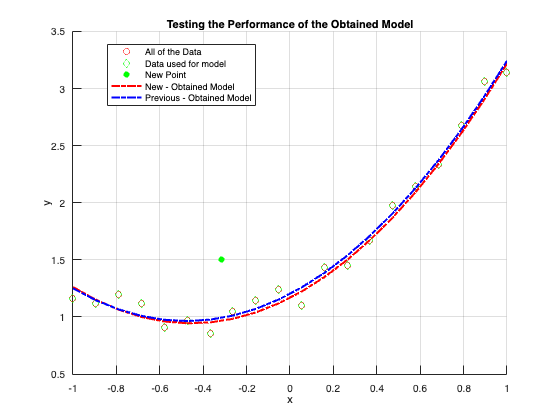

v = vT';

% Cholesky decomposition of M^T M
L = chol(B, 'lower');

% Compute LT from L
LT = L';

L_inverse =  L \ eye(size(L));

coefficientsNew = coefficients - ((L_inverse * v) * ( L_inverse * v)' * coefficients)/ (1 + vT * L_inverse * v);

px_new = M * coefficientsNew;



figure
hold on
plot(x_given, y_given, 'ro', 'DisplayName', 'All of the Data')
plot(x, y, 'gd', 'DisplayName', 'Data used for model')
scatter(x_mplus1, y_mplus1, 'g', 'filled', 'DisplayName', 'New Point');
plot(x, px_new, 'r-.', 'LineWidth', 2, 'DisplayName', 'New - Obtained Model')
plot(x, px, 'b-.', 'LineWidth', 2, 'DisplayName', 'Previous - Obtained Model')
xlabel('x')
ylabel('y')
legend('Location', 'best')
title('Testing the Performance of the Obtained Model')
grid on

## Question 2: **Nonlinear Equations for univariate case.**

a) Bisection Method is used for finding the roots of a continuous function, $f\left(x\right)$, given endpoints;$a,b$ with $f\left(a\right)\ldotp f\left(b\right)<0$ . The interval $\left\lbrack a\;\;b\right\rbrack$contains a root, $x_r$, because $f\left(a\right)$ and $f\left(b\right)$ have opposite signs.

Bisection method bisects the given interval at the midpoint, $c=\frac{a+b}{2}$ and then chooses a new interval based such that end of point of interval have opposite signs, i.e., if $f\left(a\right)\ldotp f\left(c\right)<0$, then the new interval is set to $\left\lbrack a\;\;c\right\rbrack$, else if $f\left(c\right)\ldotp f\left(b\right)<0$ then the interval is set to $\left\lbrack c\;\;b\right\rbrack$.

The above procedure is repeated until the following two conditions are simultaneously met, 

- The function value at the interval is sufficiently small, i.e., ${\left\|f\left(c\right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The new interval is sufficiently small, i.e., ${\left\|a-b\right\|}_2 <\epsilon_{\textrm{tolerance}}$

Implement the Bisection Method in the cell below to find the root of $f\left(x\right)=x^4 -{2\;x}^2 -4$ in the interval $\left\lbrack -3\;\;\;0\right\rbrack \;$using $\epsilon_{\textrm{tolerance}} ={10}^{-5}$. **Show the number of iterations the bisection method took to converge.**

Use the cell below to implement your code. 

Note: There is no need to write the function for Bisection Method. However, if you wish to implement the function, use the appendix.

%implement your bisection method here
f=@(x)x^4-2*x^2-4;

% Define interval
a = -3;
b = 0; 

% Set tolerance
tol = 1e-5;

[c,counter] = bisectionMethod(f,a,b,tol)

c = -1.7989

counter = 21

b) ** Newton-Raphson**

 Bisection Method requires the given function,$f\left(x\right)$ to be continuous, Newton-Raphson requires $f\left(x\right)$ to be continuous and differentiable. While the Newton- Raphson method converges faster than the bisection method, however, Newton-Raphson method does not guarantee convergence. Newton-Raphson works by linearising the $f\left(x\right)$, at the given initial guess, $x^{\left(0\right)}$as shown below


$$f\left(x\right)=f\left(x^{\left(0\right)} \right)+{f\left(x^{\left(0\right)} \right)}^{\prime } \left(x-x^{\left(0\right)} \right)$$


Setting the expression on the right to zero, provides an approximation to the root, and we obtain


$$x^{\left(1\right)} =x^{\left(0\right)} -\frac{f\left(x^{\left(0\right)} \right)}{{f\left(x^{\left(0\right)} \right)}^{\prime } }$$


Then, the function,$\;f\left(x\right)$, is again linearised using approximation,$x^{\left(1\right)}$as the initial guess, to obtain new approximation of the root. After $k$ iterations the new approximation for the root becomes,

  
$$x^{\left(k+1\right)} =x^{\left(k\right)} -\frac{f\left(x^{\left(k\right)} \right)}{{f\left(x^{\left(k\right)} \right)}^{\prime } }$$


The above procedure is repeated untill the following two convergence condtions are simultaneously met,  

- The function value at new guess point is sufficiently small, i.e., ${\left\|f\left(x^{\left(k+1\right)} \right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The difference between the two consecutive solutions is sufficiently small, i.e., ${\left\|\Delta x^{\left(k+1\right)} \right\|}_2 <\epsilon_{\textrm{tolerance}}$

where $\Delta x^{\left(k+1\right)} =$$x^{\left(k+1\right)} -x^{\left(k\right)}$.

Implement the **Newton-Raphson** Method in the cell below to find the root of $f\left(x\right)=x^4 -{2\;x}^2 -4$ use intial guess of $x^{\left(0\right)} =-3$ using $\epsilon_{\textrm{tolerance}} ={10}^{-5}$.  If the convergence is not reached in 100 iterations, quit the algorithm by displaying an error message indicating that Newton-Raphson failed to converge. 

Plot the 2-Norm of difference between consecutive solutions ${\left\|x^{\left(k+1\right)} -x^{\left(k\right)} \right\|}_2$  for each iteration. 

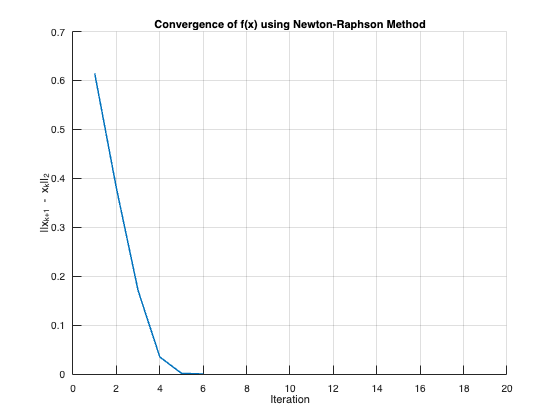


f=@(x)x^4-2*x^2-4;
% fderivative = @(x)  % write the value of derivative
fderivative = @(x) 4*x^3 - 4*x;

%Initial guess
x0 = -3;

% Set tolerance
tol = 1e-5;

% Set Max Iterations
max = 100;

[y,deltaX] = newtonraphson(f,fderivative,x0,tol,max);

figure
hold on
plot(deltaX, 'LineWidth', 1.5)
title('Convergence of f(x) using Newton-Raphson Method');
xlabel('Iteration');
ylabel('||x_{k+1} - x_{k}||_{2}');
xlim ([0,20]);
grid on; 

## Question 3:  **Nonlinear Equations for N-variables.**

 Newton-Raphson Method can be used to solve the system of nonlinear equations of N-variables, $\left\lbrack x_1 ,\;x_2 ,\;\cdots ,\;x_n \right\rbrack$shown below,


$$f_1 \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$



$$f_2 \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$
 


$$\vdots$$



$$f_N \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$


The above equations can be written as a vector valued function as shown below,


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
f_1 \left(x_1 ,x_2 ,\cdots ,x_N \right)\\
f_2 \left(x_1 ,x_2 ,\cdots ,x_N \right)\\
\vdots \\
f_N \left(x_1 ,x_2 ,\cdots ,x_N \right)
\end{array}\right\rbrack$$


where $\mathit{\mathbf{X}}=\left\lbrack x_1 ,x_2 ,\cdots ,x_N \right\rbrack$ is the vector containing all the variables.

Following the idea of unidimensional Newton-Rapshson, we start with an initial guess ${\mathit{\mathbf{X}}}^{\left(0\right)}$ and we use this to linearise the function $\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)$ around${\;\mathit{\mathbf{X}}}^{\left(0\right)}$ 


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\;$$

$$f\left({\mathit{\mathbf{X}}}^{\left(0\right)} \right)+\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(0\right)} \right)\right)\left(\mathit{\mathbf{X}}-{\mathit{\mathbf{X}}}^{\left(0\right)} \right)$$


Setting the expresson on the left side to zero, we find the approximation of the solution vector. After $k$ iterations the approximation for the solution vector can be written as 


$${\mathit{\mathbf{X}}}^{\left(k+1\right)} =$$

$${\mathit{\mathbf{X}}}^{\left(k\right)} -{\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)}^{-1} \mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$$


where $\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$ is the vector valued function evaluated at ${\mathit{\mathbf{X}}}^{\left(k\right)}$ and $\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)$ is the jacobian evaluated at ${\mathit{\mathbf{X}}}^{\left(k\right)}$. The structure of the Jacobian is given by,


$$\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{cccc}
\frac{\partial f_1 }{\partial x_1 } & \frac{\partial f_1 }{\partial x_2 } & \cdots  & \frac{\partial f_1 }{\partial x_n }\\
\frac{\partial f_2 }{\partial x_1 } & \frac{\partial f_2 }{\partial x_2 } & \cdots  & \frac{\partial f_2 }{\partial x_n }\\
\vdots  & \vdots  & \ddots  & \vdots \\
\frac{\partial f_n }{\partial x_1 } & \frac{\partial f_n }{\partial x_2 } & \cdots  & \frac{\partial f_n }{\partial x_n }
\end{array}\right\rbrack$$


The above procedure is repeated untill the following two convergence condtions are simultaneously met,  

- The function value at new guess point is sufficiently small, i.e., ${\left\|\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k+1\right)} \right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The difference between the two consecutive solutions is sufficiently small, i.e., ${\left\|{\mathit{\mathbf{X}}}^{\left(k+1\right)} -{\mathit{\mathbf{X}}}^{\left(k\right)} \right\|}_2 <\epsilon_{\textrm{tolerance}}$

Find a solution of the following system of three nonlinear equations using Newton-Raphson method.


$${9x}_{1\;}^{2\;} +x_{2\;}^{2\;} +x_3^2 \;=3$$



$$x_{1\;}^{2\;} +\;{2x}_2^2 -x_{3\;} =2$$



$$x_{1\;} +x_{2\;} +12x_3 =5$$


Note that this can be expressed as 

$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
{9x}_{1\;}^{2\;} +x_{2\;}^{2\;} +x_3^2 -3\\
x_{1\;}^{2\;} +\;{2x}_2^2 -x_{3\;} -2\\
x_{1\;} +x_{2\;} +12x_3 -5
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$,        where $\mathit{\mathbf{X}}={\left\lbrack \begin{array}{ccc}
x_1  & x_2  & x_3 
\end{array}\right\rbrack }^T$

a) Write a MATLAB function named *evaluateEquations(x)*, that evaluates the above equation at a given input vector. Use the provided $\mathit{\mathbf{X}}$ to check your implementation.

Use the framework of the function provided in the Appendix. 

% X in this case is an example
 
X = [2;3;4];

f  = evaluateEquations(X)

f =     58
    16
    48


b) Write a MATLAB function named *evaluateJacobian()*, that evaluates the Jacobian of the above equations. Use the provided $\mathit{\mathbf{X}}$ to check your implementation.

Use the framework of the function provided in the Appendix.  

X = [2;3;4];
J  = evaluateJacobian(X)

J =     36     6     8
     4    12    -1
     1     1    12


**Newton-Raphson **

c) Implement the Newton-Raphson method, use the function named *NewtonRaphson() *to write the code for this. 

Start with intial guess, $X^{\left(0\right)} ={\left\lbrack \begin{array}{ccc}
0 & 0 & 0
\end{array}\right\rbrack }^T$  and then find a suitable intial guess. Plot the 2-Norm of difference between consecutive solutions ${\left\|{\mathit{\mathbf{X}}}^{\left(k+1\right)} -{\mathit{\mathbf{X}}}^{\left(k\right)} \right\|}_2$ for each iteration. 

Use the framework of the function provided in the Appendix.  In the  *NewtonRaphson() *function use the methods implemented in part (a) and (b).

Xguess = [0.5 0.5 0.5]; % startinginitial guess 
% write your code here
func = @evaluateEquations;
Jac = @evaluateJacobian;
tol = 1e-5;
[X,normDeltaX]  = NewtonRaphson(func,Jac,Xguess,tol)

X =     0.4559
    1.0212
    0.2936


normDeltaX =     0.8109    0.2320    0.0250    0.0003    0.0000


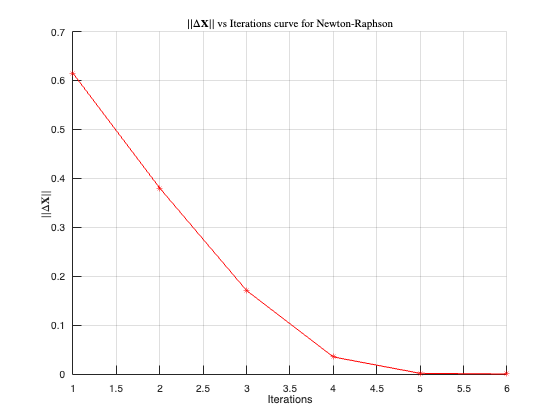

figure
hold on
plot(deltaX,'r-*')
xlabel('Iterations')
ylabel(' $ || \Delta \textbf{X} || $ ', 'Interpreter', 'latex')
grid on
title(' $ || \Delta \textbf{X} || $  vs Iterations curve for Newton-Raphson', 'Interpreter', 'latex')

**Newton-Raphson with Broyden's method to approximate Jacobian**

d) Suppose you do not have access to the Jacobian of  the nonlinear eqautions, use the Broyden's method  to compute/ update the Jacobian.  

At the $(k+1)^{th}$ iteration of Newton Raphson, the soltuion vector $\mathit{\mathbf{X}}$  is given by 


$${\mathit{\mathbf{X}}}^{\left(k+1\right)} =$$

$${\mathit{\mathbf{X}}}^{\left(k\right)} -{\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)}^{-1} \mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$$


let, $J_{k\;} =\;\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)$. Using the Broyden's update, $J_{k\;}$ can be computed as 


$$J_{k\;} =J_{k-1} +\;\frac{\;\left(\;\;\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)-\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k-1\right)} \right)\;\;\right)\;-\;\;J_{k-1} \;\;\left({\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \right)\;}{{\left\|\;\;\left({\;\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)} \;\;\right)\;\;\right\|}_2^{2\;} }{\left({\;\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)} \;\right)}^T$$


Write a MATLAB function named* NR_Broyden_Jacobian()*, that evaluates the Jacobian of the above equations. 

Use the initial guess,$X^{\left(0\right)}$ you used in part c). For the intial guess for Jacobian $J_0  =I_{n\times n}$, where $I_{n\times n}$ is the identity matrix and $n$ is the number of equations.

Use the framework of the function provided in the Appendix



func =@evaluateEquations;
[Xout,deltaXBroyden]  = NR_Broyden_Jacobian(func, Xguess,1e-5)

Xout =     0.4559
    1.0212
    0.2936


deltaXBroyden =     2.6693   12.6145   12.9067    0.5538    0.3398    0.0805    0.0287    0.1517    0.3164    0.1525    0.4376    0.3606    0.0090    0.0058    0.0226    0.0089    0.0002    0.0001    0.0000


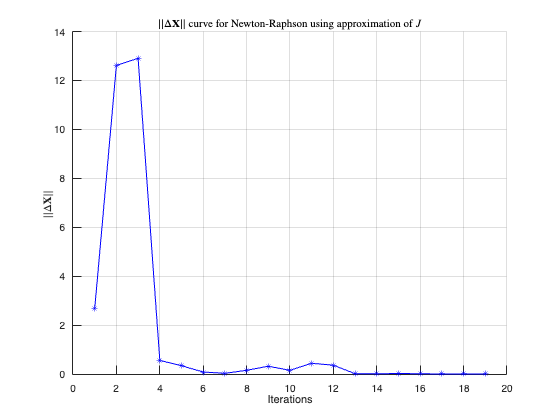

figure
hold on
plot(deltaXBroyden,'b-*')
xlabel('Iterations')
ylabel(' $ || \Delta \textbf{X} || $ ', 'Interpreter', 'latex')
grid on
title(' $ || \Delta \textbf{X} || $  curve  for Newton-Raphson using approximation of $J$', 'Interpreter', 'latex')

**Newton-Raphson with Broyden's method to approximate Inverse of Jacobian**

e)  In part d) , you implemented the Broyden's method for updating the Jacobian, in this part use the Broyden's update for computing inverse of Jacobian. The inverse of Jacobian can be computed as 


$$J_{k\;}^{-1} =J_{k-1}^{-1} +\;\frac{\;\left(\;{\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \;\right)-\;J_{k-1}^{-1\;} \;\;\left(\;\;\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)-\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k-1\right)} \right)\;\;\right)\;}{{\left(\;{\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \;\right)}^{T\;} J_{k-1}^{-1} \;\;\left(\;\;\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)-\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k-1\right)} \right)\;\;\right)}\left({\left(\;{\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \;\right)}^{T\;} \;J_{k-1}^{-1} \right)$$


Write a MATLAB function named* NR_Broyden_InvJacobian()*, that evaluates the Jacobian of the above equations. 

Use the initial guess,$X^{\left(0\right)}$ you used in part c). For the intial guess for inverse of Jacobian $J_0^{-1} =I_{n\times n}$, where $I_{n\times n}$ is the identity matrix and $n$ is the number of equations.

Use the framework of the function provided in the Appendix.


func =@evaluateEquations;

[Xout,Iteration,deltaXBroyden]  = NR_Broyden_InvJacobian(func, Xguess,1e-5)

Xout =    -0.6195
    0.7911
    0.3620


Iteration = 25

deltaXBroyden =     2.6693   21.7544  133.5450  135.4936    2.8773    0.6575    1.3113    3.4471    1.5628    1.4542    0.7271    0.6019    1.6267    2.6925    2.8737    0.0510    0.0133    0.0041    0.0633    0.0229    0.0039    0.0001    0.0000    0.0000    0.0000


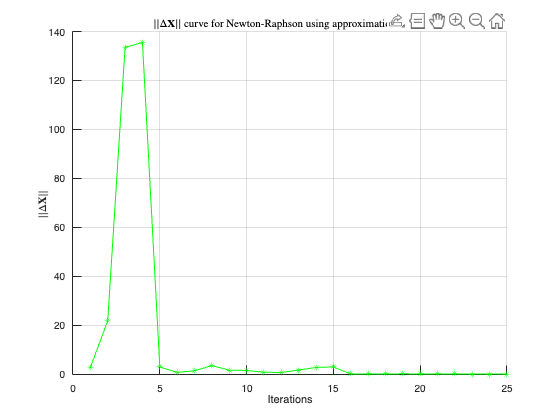

figure
hold on
plot(deltaXBroyden,'g-*')
xlabel('Iterations')
ylabel(' $ || \Delta \textbf{X} || $ ', 'Interpreter', 'latex')
grid on
title(' $ || \Delta \textbf{X} || $  curve  for Newton-Raphson using approximation of $J^{-1}$', 'Interpreter', 'latex')

f)  Given a nonlinear system with $n$ number of nonlinear equations, shown below,


$$f_1 \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\;=3x_{1\;} -2x_{1\;}^2 -2x_{2\;} +1=0$$



$$f_i \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\;\;=3x_{i\;} -2{x_i }_{\;}^2 -x_{i-1} -2x_{i+1} +1=0,\;\;\;\;\;\textrm{for}\;\;\;1<i<n$$


 
$$f_n \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)=3x_{n\;} -2{x_n }_{\;}^2 -x_{n-1} +1=0$$


where, $x_1$, $x_2$, ..., $x_n$  are the variables. 

The nonlinear vector of equations can written as, 


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
f_1 \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\\
f_2 \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\\
\vdots \\
f_i \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\\
\vdots \\
f_n \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
0\\
\vdots \\
0
\end{array}\right\rbrack$$


The Matlab function to evalaute the above function is named *nlfunction() *and  it is  provided to you in appendix. 

Suppose you  do not have access to the jacobian, so you chose to solve the above nonlinear function using Broyden's methods you developed in part (d) and (e). The code cell below uses the Broyden's algorithms you implemented in paer d) and  e) to solve the above nonlinear system for different size of the system ranging from  $10\le n\le 200$. 

Run the cell below and explain the results in Figure Question 3 f.

clear all
func1 = @nlfunction;
c = 1

c = 1

N = 200

N = 200

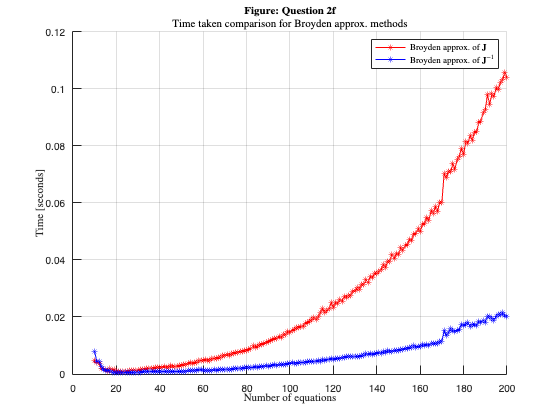

time_BroydenIJ = zeros(N-10+1,1);
time_BroydenJ = zeros(N-10+1,1);
for I=10:N
Xguess = zeros(I,1);
brIJstart =tic ;
[XBrIJ,deltaXBroyden]  = NR_Broyden_InvJacobian(func1,Xguess,1e-6);
time_BroydenIJ(c) = toc(brIJstart) ;

brJstart =tic ;
[XBrJ,deltaXBroyden]  = NR_Broyden_Jacobian(func1,Xguess,1e-6);
time_BroydenJ(c) = toc(brJstart) ;

c =c +1;
end

figure()
clf
hold on 
plot(10:N,time_BroydenJ,'r-*')
plot(10:N,time_BroydenIJ,'b-*')

legend('Broyden approx. of $\textbf{J}$' ,'Broyden approx. of $\textbf{J}^{-1}$','Interpreter','latex')
title({'\textbf{Figure: Question 2f}','Time taken comparison for Broyden approx. methods'}, 'Interpreter', 'latex')
ylabel('Time [seconds]', 'Interpreter', 'latex')
xlabel('Number of equations', 'Interpreter', 'latex')
grid on 

- We observe that the computational cost of the Broyden Method to approximate the Jacobian is higher than that of the computational cost of the Inverse Broyden Method. This is most likely due to the fact that in the non-inverse Broyden method, we must solve *J \ F*, which is computationally intensive. Namely, computing the inverse is computationally expensive as it done in O(n^3). This behaviour is observed in the previous figure, where as the number of equations increases, so does the difference between the two methods. Namely, when the number of equations is relatively small, the methods have a similar time complexity, but as the number of equation grows, the Inverse Broyden Method becomes much more advantageous . 

## **Question 4:  Eigenvalues**

The Power Iteration method is used to compute the dominant eigen value  and the  eigen vector associated with the  dominant eigen value of a given matrix. Any random vector $x_0$ can be written as the linear combination of $n$ independent eigen vectors of a matrix ${\mathit{\mathbf{A}}}_{n\times n}$ as 


$${\mathit{\mathbf{x}}}_{0\;} =c_{1\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\mathit{\mathbf{v}}}_2 +\cdots +c_n {\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;} \;\;\;$$
                                             
$$\left(1\right)$$


On multiplying the above with matrix $\mathit{\mathbf{A}}$ we get,


$${\mathit{\mathbf{A}}\;\mathit{\mathbf{x}}}_{0\;} =c_{1\;} \mathit{\mathbf{A}}{\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\mathit{\mathbf{A}}\;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \mathit{\mathbf{A}}{\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;}$$
                                  
$$\left(2\right)$$


The vectors ${\mathit{\mathbf{v}}}_i$'s are the eigen vectors of matrix $\mathit{\mathbf{A}}$, therefore, $\mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}} =\lambda_{i\;} {\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}}$. The symbol  $\lambda_{i\;}$denotes the eigen value corresponding to eigen vector ${\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}}$.  


$${\mathit{\mathbf{A}}\;\mathit{\mathbf{x}}}_{0\;} =c_{1\;} \lambda_{1\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\lambda_{2\;} \;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \lambda_{n\;} {\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;\;}$$
                                
$$\left(3\right)$$


Equation (3), can be  generalised to 


$${{\mathit{\mathbf{A}}}^{k\;} \;\mathit{\mathbf{x}}}_{0\;} =c_{1\;} \lambda_{1\;}^{k\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\lambda_{2\;}^k \;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \lambda_{n\;}^{k\;} {\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;\;}$$
                              
$$\left(4\right)$$


Without loss of generality (4) can be written as


$${{\mathit{\mathbf{A}}}^{k\;} \;\mathit{\mathbf{x}}}_{0\;} =\lambda_{1\;}^{k\;} \left(c_{1\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\frac{\lambda_{2\;}^k }{\lambda_{1\;}^{k\;} }\;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \frac{\lambda_{n\;}^{k\;} }{\lambda_{1\;}^{k\;} }{\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;\;} \right)$$
                     
$$\left(5\right)$$


Assuming that $\left|\lambda {\;}_1 \right|>$$\left|\lambda_2 \right|>\cdots \left|\lambda_n \right|$.  As $k\to \infty$, the terms with  $\frac{\lambda_{j\;}^k }{\lambda_{1\;}^{k\;} }\to 0$.  Thus, as $k\to \infty$,  ${{\mathit{\mathbf{A}}}^{k\;} \;\mathit{\mathbf{x}}}_{0\;}$converges to the eigen vector ${\mathit{\mathbf{v}}}_{1\;}$ corresponding to the largest eigen value. Write an iterative algorithm which computes the eigen vector and eigen value using the following recurssive formula,


$${\mathit{\mathbf{v}}}^{\left(k+1\right)} =\;\frac{\mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}^{\left(k\right)} }{\parallel \mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}^{\left(k\right)} \parallel }$$
                                                                   
$$\left(6\right)$$
   

where ${\mathit{\mathbf{v}}}^{\left(k+1\right)}$ is the eigen vector at ${\left(k+1\right)}^{\textrm{th}}$iteration.

 Stop the algorithm using when the $\parallel {\mathit{\mathbf{v}}}^{\left(k+1\right)} \;-{\mathit{\mathbf{v}}}^{\left(k\right)} \parallel \;<\epsilon_{\textrm{tol}}$, where $\epsilon_{\textrm{tol}}$ is the input tolerance value. 

Write a MATLAB function power_method(A,tol) that uses power iteration algorithm to compute the dominant eigen value and the eigenvector. 

Use the cell below to test the your function, you can use MATLAB's built in function, eig (see MATLAB documentation) to compare your answers.

M = randi(15,5)/10;
A = M'*M;
tol = 1e-4

tol = 1.0000e-04

[V,D] = eig(A)

V =     0.1612    0.0866    0.6396   -0.6639    0.3415
    0.5609   -0.0373    0.2660    0.6282    0.4676
   -0.7221   -0.3595    0.1029    0.1642    0.5585
    0.3692   -0.6057   -0.5350   -0.3554    0.2905
   -0.0412    0.7036   -0.4726   -0.1070    0.5181


D =     0.0543         0         0         0         0
         0    0.1887         0         0         0
         0         0    0.3017         0         0
         0         0         0    0.9704         0
         0         0         0         0   18.6549


[e,v]= power_method(A,tol)

e = 18.6549

v =     0.3416
    0.4676
    0.5585
    0.2905
    0.5181


# Appendix

## *Forward Sub*

function y = forward_sub(L,b)
% y is the vector - Here we let Ux = y to solve for LUx = b  
% L is the lower triangular matrix
% Ly = b --> solve with forward sub

    n = length(b); 
    y = zeros(n, 1);
    for i = 1:n 
        y(i) = ( b(i) - L(i, 1:i-1) * y(1:i-1,1) ) / L(i,i) ;
    end
end 


## *Backward Sub*

function X = backward_sub(U,y)
% X is the vector 
% U is the upper triangular matrix
% Ux = y --> solve with backward sub
    [~, n] = size(U); 
    X = zeros(n, 1); 
    for i = n:-1:1
        if i == n
            X(i) = y(i) / U(i, i);
        else
            X(i) = (y(i) - U(i, i+1:n) * X(i+1:n)) / U(i, i);
        end
    end
end

## **Vandermonde Matrix**

function M = PolynomialMatrix(x,n)
% write your code here
% n is the degree of the polynomil
% x is the vector of input data

% Scale x


m = length(x);
M = zeros(m, n+1);

% Construct the polynomial matrix
for i = 1:m
    for j = 1:(n+1)
        M(i, j) = x(i)^(j-1);
    end
end

end

Function provided for Question 2 part e)

function [F] = nlfunction(x)
% x is a colmns vecotr.
% Evaluate the vector function

n = length(x);
F = zeros(n,1);
i = 2:(n-1);
F(i) = (3-2*x(i)).*x(i)-x(i-1)-2*x(i+1) + 1;
F(n) = (3-2*x(n)).*x(n)-x(n-1) + 1;
F(1) = (3-2*x(1)).*x(1)-2*x(2) + 1;

end

Question 2) a)

function [x, iterations] = bisectionMethod(f,a,b,tol)

% inputs :
% f is  the function 
% ( it is supplied as a handle for the nonlinear  fucniton f)
% in the Q2b it the fiunction f is already defined for you

% a and b: specify the interval
% tol is the desired tolerance 

%outputs:
% x : is the solution of the nonlinear equation
% iterations is thenumber of iterations your method took to converge.

% write your code here 
    iterations = 0;
    while true
        c = (a + b) / 2; 
        if norm( f(c) , 2) < tol && norm( b-a, 2) < tol 
            x = c;
            return;
        elseif (f(a) * f(c) < 0)
            b = c;
        else
            a = c;
        end 
        iterations = iterations + 1;
    end 
end

Question 2 b)

function [x,normDeltaX]=newtonraphson(f,fderiv,x0,tol,itermax)

% inputs :
% f is  the function 
% ( it is supplied as a handle for the nonlinear  fucniton f)
% in the Q2b it the function f is already defined for you

%fderiv is  the derivative of nonlinear function 
% ( it is supplied as a handle for the nonlinear  fucniton f)

% x0 is the initial guess
% tol is the desired tolerance 
% itermax is the maximum number of iterations


%outputs:
% x : is the solution of the nonlinear equation
%normdeltaX is the norm of deltaX at each iteration


% Keep track of those values 
    x = x0;                             % Initial Guess x0 
    normDeltaX = zeros(itermax, 1);     % Initialize normDeltaX array

    for iteration = 1:itermax 
    
        funcX = f(x);
        derivativeFuncX = fderiv(x);
    
        deltaX = - funcX / derivativeFuncX; 

        x_next = x + deltaX;            % x_k+1 

        % Calculate the change in x for convergence check
        normX = norm(x_next - x,2);
        normDeltaX(iteration) = normX;

        x = x_next;                     % Set x_k to x_k+1 for next iteration

        % Check for Convergence
        if normX < tol && norm(f(x_next),2) < tol           
            normDeltaX = normDeltaX(1:iteration); % Trim excess zeros from normDeltaX
            return;
        end
    end

    % Maximum iterations reached without convergence
    error(['Newton-Raphson failed to converge within ', num2str(itermax), ' number of iterations.']);
end

Question 3) a)

function f  = evaluateEquations(x)

 f = zeros(3,1);

 f(1) = 9*x(1)^2 + x(2)^2 + x(3)^2 - 3;
 f(2) = x(1)^2 + 2*x(2)^2 - x(3) - 2;    
 f(3) = x(1) + x(2) + 12*x(3) - 5;

end 


Question 3) b)

function J  = evaluateJacobian(x)
    
    J = zeros(3,3);
   
    J(1, 1) = 18*x(1);  % PD of 1st eq. w.r.t. x1
    J(1, 2) = 2*x(2);   % PD of 1st eq. w.r.t. x2
    J(1, 3) = 2*x(3);   % PD of 1st eq. w.r.t. x3
    
    J(2, 1) = 2*x(1);   % PD of 2nd eq. w.r.t. x1
    J(2, 2) = 4*x(2);   % PD of 2nd eq. w.r.t. x2
    J(2, 3) = -1;       % PD of 2nd eq. w.r.t. x3
    
    J(3, 1) = 1;        % PD of 3rd eq. w.r.t. x1
    J(3, 2) = 1;        % PD of 3rd eq. w.r.t. x2
    J(3, 3) = 12;       % PD of 3rd eq. w.r.t. x3

end

Question 3) c)

function [Xout, normDeltaX] = NewtonRaphson(func, Jac, Xguess, tol)
    % func is the handle for evaluateEquations().. it is created for you
    % Jac i is the handle for evaluateJacobian().. it is created for you

    % Xguess is the initial Guess vector :
    % tol is the desired tolerance

    % Xout is the ouput vector
    % normDeltaX stores the norm of the deltaX at each iteration

    
    % Initialize variables
    X = Xguess(:);   % Initial guess + (:) Makes it stay a column vector
    normDeltaX = []; % Store normDeltaX at each iteration
    i = 0;
    maxIter = 100;
    while true
        i = i + 1;
        F = func(X);                        % Evaluate func(X)
        J = Jac(X);                         % Evaluate Jac(X)

        deltaX = - J \ F;                   % Solve J_k * deltaX = -f(x_old) 
        X_next = X + deltaX;                % X_k+1 = X_old + deltaX  
        
        normX = norm(deltaX, 2);            % Plot || deltaX ||_2
        normDeltaX(i) = normX;              % Plot || deltaX ||_2

        % Check for Convergence
        if norm(func(X_next)) < tol && normX < tol
            Xout = X_next;
            return;
        end
        
        X = X_next;                             % Set X_k to X_k+1 for next iteration 
        if i == maxIter
            error('Newton-Raphson did not converge within maximum iterations.');
        end
    end

end

Appendix: Question 3 d)

function [Xout,deltaXBroyden]  = NR_Broyden_Jacobian(func, Xguess,tol)
    % func is the handle for evaluateEquations().. it is created for you
    % Xguess is a Column Vector , it is the initial Guess vector :
    % tol is the desired tolerance

    % Xout is the ouput vector
    % normDeltaX stores the norm of the deltaX at each iteration


    J = eye(size(Xguess,1)); %keep this line
    

    % Initialize variables
    maxIter = 1000;  % Maximum number of iterations
    X = Xguess(:);   % Initial guess + (:) Makes it stay a column vector
    deltaXBroyden = []; % Store normDeltaX at each iteration
    i = 0;

    while (i < maxIter)
        i = i + 1;
        F = func(X);                            
        
        deltaX = - J \ F;                       % Solve J_k * deltaX = -f(x_old) 

        X_next = X + deltaX;                    % X_k+1 = X_old + deltaX || X_k+1 
        deltaXBroyden(i) = norm(X_next - X);

        % Check for Convergence
        if norm(func(X_next)) < tol || norm(deltaX) < tol 
            Xout = X_next;
            return;
        end

        % Update J using Broyden's method
        changeF = func(X_next) - F;
        normChangeXSquared = deltaX' * deltaX;

        J = J + (((changeF - J * deltaX) * deltaX' )/ normChangeXSquared) ;
        
        X = X_next;                             % Set X_k to X_k+1 for next iteration
    end
    
    if i == maxIter
        error('Newton-Raphson did not converge within maximum iterations.');
    end
end


Appendix: Question 3 e)

function [Xout,i,deltaXBroyden]  = NR_Broyden_InvJacobian(func, Xguess,tol)
%func is the handle for evaluateEquations().. it is created for you
% Xguess is a Column Vector , it is the initial Guess vector :
% tol is the desired tolerance

% Xout is the ouput vector
% normDeltaX stores the norm of the deltaX at each iteration


    inverseJ = eye(size(Xguess, 1)); % Initialize the inverse Jacobian

    % Initialize variables
    maxIter = 1000000;  % Maximum number of iterations
    X = Xguess(:);   % Initial guess
    deltaXBroyden = []; % Store norm of deltaX at each iteration
    i = 0;

    while (i < maxIter)
        i = i + 1;
        F = func(X);                            
        
        deltaX  = -inverseJ * F;

        X_next = X + deltaX;                    % X_k+1 = X_old + deltaX

        deltaXBroyden(i) = norm(deltaX);

        % Check for Convergence
        if norm(func(X_next)) < tol || norm(deltaX) < tol
            Xout = X_next;
            return;
        end

        % Update inverseJ using Broyden's method
        changeF = func(X_next) - F;
        numerator = deltaX - inverseJ * changeF;
        denum = deltaX' * inverseJ * changeF; 

        inverseJ = inverseJ + ((numerator* (deltaX' * inverseJ)) / denum) ; 
        
        X = X_next;                             % Set X_k to X_k+1 for next iteration
    end
    
    if i == maxIter
        error('Newton-Raphson did not converge within maximum iterations.');
    end
end

 Appendix Question 4

function [eig_val,eig_vector]=  power_method(A,tol)
% Find the largest eigen value for the input matrix and the eigen vector
% associated with it.
% Input : A is the matrix 
%         tol is the tolerance
% Output:
% eig_val is the largest eigen values 
% eig_vector is the eigen vector associsted with the larges eigen value

% Initialize a random vector
[n,~] = size(A);            % Get size of A
v = ones(n, 1);             % Initialize a vector of one [1,1,1....]
v = v / norm(v);            % Normalize v       

while true
    w = A * v;              % w <- Av
    
    % Compute the eigenvalue
    eig_val = w' * v;       % w' * v ==> (A*v)' * v ==> v' * A' * v
    
    v = w / norm(w);        % Normalize v
    
    % Check for convergence
    if norm( w - eig_val * v ) < tol
        break;
    end
end

% Return the eigenvalue and eigenvector
eig_vector = v;
end